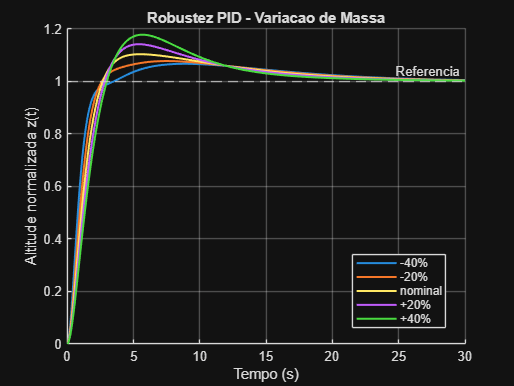

% variacao_pid.m
% G1 - Controle de Altitude de Drone
% Responsavel: Kauã
% Objetivo: gerar a figura de robustez do PID para variacao de massa.

%clear; clc; close all;

% Parametros nominais
b = 0.5;
Kp = 0.434995085666;
Ki = 0.042131655455;
Kd = 0.783406314789;
Tf = 0.369512150729;

% Controlador PIDF usado por Arthur: C(s)=Kp+Ki/s+Kd*s/(Tf*s+1)
C_pid = pid(Kp, Ki, Kd, Tf);

t = 0:0.01:30;
m_vals = [0.72 0.96 1.20 1.44 1.68];
legendas = {'-40%', '-20%', 'nominal', '+20%', '+40%'};

figure; hold on; grid on;
for i = 1:length(m_vals)
    m = m_vals(i);
    G_var = tf(1/m, [1 b/m 0]);
    T_var = feedback(C_pid*G_var, 1);
    y = step(T_var, t);
    plot(t, y, 'LineWidth', 1.5);
end
yline(1, '--', 'Referencia');
legend(legendas, 'Location', 'best');
title('Robustez PID - Variacao de Massa');
xlabel('Tempo (s)');
ylabel('Altitude normalizada z(t)');

exportgraphics(gcf, 'fig_variacao_pid.png', 'Resolution', 600);